## **Optimization Division**

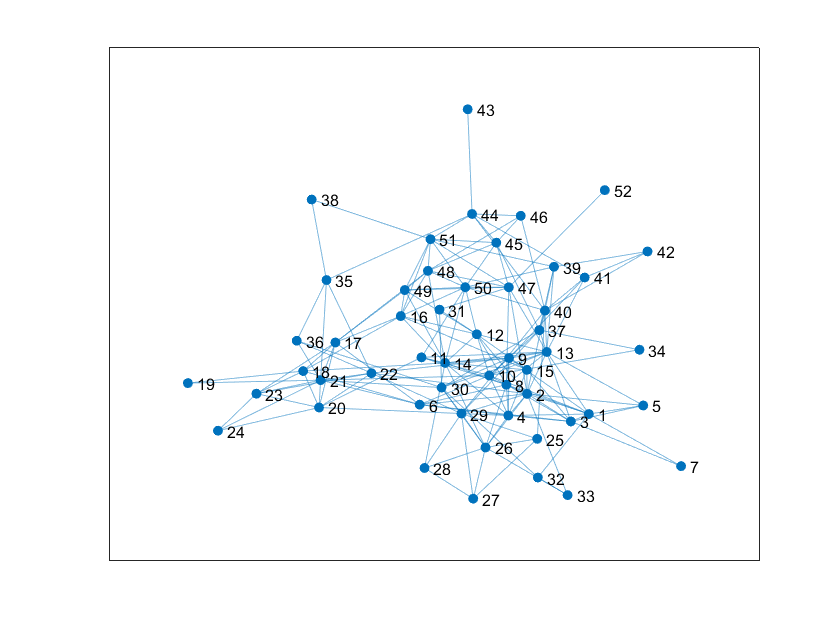

clear all; close all; clc
% % Load matrix for imputation of subregion
M = readmatrix('../_aux/cp_exp_unique_1.csv');
l = length(M(:,1));
    
%%
% Travel time matrix
PT = readmatrix('../_aux/PT.csv',"NumHeaderLines",1); 
% Distance matrix
PD = readmatrix('../_aux/PD.csv',"NumHeaderLines",1);  

ind = zeros(l);
m = max(M(:,4));
ad_sub = zeros(m,m);
for i=1:l
    ind = find(PD(i,:) == min(PD(i,M(:,4)~=M(i,4))));
    % Neighbours adyacent to subregion M(i,4)
    ad_sub(M(i,4),M(ind,4)) = 1;
end

ad_sub = (ad_sub + ad_sub')/2>0;
G = graph(ad_sub);
gr = plot(G);
saveas(gr,'../mapas/graph_sub','svg')

Load dataset for the problem

Ms = readmatrix('../_aux/sub_exp_unique_.csv');

Additive statistic for balance

X = 0.8*Ms(:,2)+0.1*Ms(:,3)+0.1*Ms(:,4); % Diligencias + Address + Km2 (all scaled)

**We declare the optimization variables**

D = optimvar('D',length(X),25,'Type','integer','LowerBound',0,'UpperBound',1);
T = optimvar('T',25,25,'LowerBound',0);

**We declare the constraints**

Define the aggregated statistic for every region

y = X'*D; 

The next constraint require every subregion $k$ to be assigned to exactly one region $r$

assignment = sum(D,2) == ones(length(X),1);

Aditional constraints (LP formulation)

for i=1:25
    for j=1:25
        additional1(i,j) = T(i,j) >= y(j)-y(i);
        additional2(i,j) = T(i,j) >= y(i)-y(j);
    end
end

Adyacency constraints & Grouping constraints

for i=1:length(X)
    for j=i+1:length(X)
        if ad_sub(i,j)==0 && i~=j
            ad_const(i,j,1:25) = reshape(D(i,:)+D(j,:)<=ones(1,25),1,1,25);
        end
        if Ms(i,7)~=Ms(j,7) && i~=j
            gp_const(i,j,1:25) = reshape(D(i,:)+D(j,:)<=ones(1,25),1,1,25);
        end
    end
end

Declare the optimization problem

optDiv = optimproblem;


The objective function to minimize is the sum of the absolute value of differences.

balance = sum(sum(T));
optDiv.Objective = balance;

Include the constraints in the problem.

optDiv.Constraints.as = assignment;
optDiv.Constraints.ad1 = additional1;
optDiv.Constraints.ad2 = additional2;
optDiv.Constraints.adc = ad_const;
optDiv.Constraints.adc = gp_const;

## **Solution to the problem**

Solving problem using intlinprog.
LP:                Optimal objective value is 0.000000.                                             

Cut Generation:    Applied 2 Gomory cuts, and 5 mir cuts.                                           
                   Lower bound is 0.000000.                                                         

Heuristics:        Found 2 solutions using diving.                                                  
                   Upper bound is 343.695678.                                                       
                   Relative gap is 99.71%.                                                         

Cut Generation:    Applied 8 Gomory cuts,                                                           
                   and 116 flow cover cuts.                                                         
                   Lower bound is 0.000000.                                                         
                   Relative gap is 99.71%.             

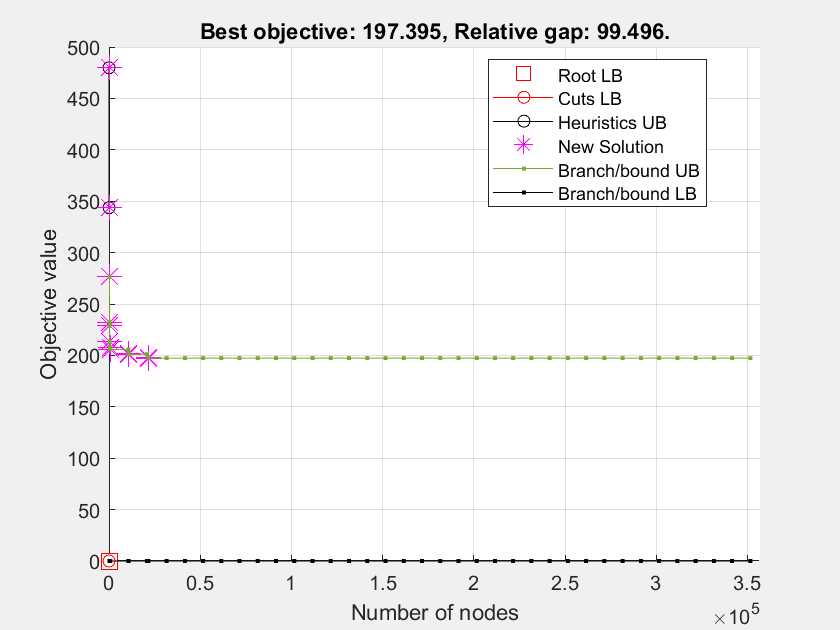

Solver stopped prematurely. Integer feasible point found.

Intlinprog stopped because it exceeded the time limit,
options.MaxTime = 18000 (the selected value). The intcon
variables are integer within tolerance,
options.IntegerTolerance = 1e-05 (the default value).



opts = optimoptions('intlinprog','MaxTime',18000, 'Display','iter','PlotFcn',@optimplotmilp);
[sol,fval,exitflag,output] = solve(optDiv,'options',opts);

**Optimal division**

sol.D

ans =     1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0    1.0000         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0    1.0000         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0    1.0000         0         0         0         0         0         0         0         0         0 

**Optimal value function**

fval

fval = 197.3947

if isempty(sol) % If the problem is infeasible or you stopped early with no solution
    disp('The solver did not return a solution.')
    return % Stop the script because there is nothing to examine
end




Examine the exit flag and the infeasibility of the solution.

exitflag

exitflag =     IntegerFeasible


infeas1 = max(max(infeasibility(assignment,sol)))

infeas1 = 7.9536e-13

res = [Ms, sol.D]

res =     1.0000    1.0948    1.5882    2.9762   19.3246  -99.1627    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    2.0000    0.6313    0.9758    3.0088   19.3101  -99.1290    1.0000    2.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0    1.0000         0         0         0         0         0         0         0         0         0         0
    3.0000    0.4352    0.4360    3.0696   19.2757  -99.1960    1.0000    3.0000         0         0         0         0         0         0         0         0         0         0         0         0    1.0000         0         0         0         0         0         0         0         0         0         0         0         0
 

colNames = {'reg_sub','num_diligencias_sub', 'num_addr_sub', 'area_sqkm_sub', ...
    'lat_c', 'lon_c', 'region', 'id', ...
    'r1','r2','r3','r4','r5','r6','r7','r8','r9','r10',...
    'r11','r12','r13','r14','r15','r16', 'r17','r18','r19','r20','r21','r22','r23','r24','r25'};
sTable = array2table(res,'VariableNames',colNames);
writetable(sTable,'../results/sub_exp_res.csv')
